## Opgave 1 Sandsynlighedsteori

En lateral flow test for påvisning af malaria har en sensitivitet på 92% og en specifititet på 90%. 200 personer testes, udaf dem er 50 smittet med malaria.

sens = 0.92; % Chance for Positiv test ved smitte
spec = 0.90; % chance for negativ test ved ikke smitte
n = 200;
ndisease = 50;

a) Hvor mange af de 50 smittede forventes at få en negativ test (altså få at vide at de ikke er smittede, selvom de er)? 

ndisease*(1-sens)

ans = 4.0000

b) Hvad er den totale sandsynlighed for at en tilfældigt udvalgt af de 200 får en positiv test? 

pr_pos_n_smitte = sens * (ndisease/n);
pr_pos_n_ik_smitte = (1-spec) * (1-(ndisease/n));
pr_pos = pr_pos_n_smitte + pr_pos_n_ik_smitte

pr_pos = 0.3050

c) Givet at en person af de 200 personer får en positiv test, hvad er sandsynligheden for at vedkommende er smittet?

% Bayes rule
pr_pos_I_smittet = sens;
pr_smittet = ndisease/n;
pr_smittet_I_pos = pr_pos_I_smittet*pr_smittet/pr_pos

pr_smittet_I_pos = 0.7541

## Opgave 2 Stokastisk variable

Der er givet en Stokastisk variable X med tæthedsfunktionen (pdf) fx(x):

$f_x \left(x\right)=\frac{1}{4}\;$Når 0 <= x < 2

$f_x \left(x\right)=\frac{1}{2}\;$Når 2 <= x <= 3

$f_x \left(x\right)=0$ ellers

a) Bestem og skitsér fordelingsfunktionen (CDF) 𝐹𝑋(𝑥) for 𝑋 i intervallet -1 til 4. 

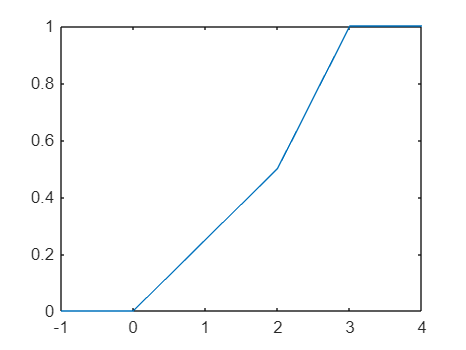

syms x

fx(x) = piecewise(0 <= x < 2, 1/4, 2 <= x <= 3, 1/2, 0);

cdf = int(fx, -inf, x);

fplot(cdf,[-1 4])

b) Opstil udtryk for og bestem middelværdien EX for 𝑋. 

syms x
meanx = int(@(x)x*fx, x, -inf, inf)

$$meanx = \frac{7}{4}$$

Vi har en ny variabel 𝑌 = 2 𝑋 + 3. 

c) Opstil udtryk for og bestem middelværdi EY for 𝑌. 

syms x

Y = 2*fx(x) + 3

$$Y = \left\{ \begin{array}{cl} \frac{7}{2} & \text{ if }x\in \left[0,2\right)\\ 4 & \text{ if }x\in \left[2,3\right]\\ 3 & \mathrm{otherwise} \end{array}\right.$$

Da Y er en linear funktion med x (Y = ax +b)

Kan man bruge følgende formel E[Y] = E[aX + b] = a * E[X] + b

meany = 2 * meanx + 3

$$meany = \frac{13}{2}$$

d) Opstil udtryk for og bestem varians Var(Y) for 𝑌.

På samme måde som forrige opgave kan man finde variansen for Y ved følgende formel:

Var[Y] = Var[aX+b] = a^2(E[X^2]*E[X]^2) = a^2 * Var[X]

syms x
varx = int(@(x)((x-meanx)^2)*fx(x), x, -inf, inf)

$$varx = \frac{37}{48}$$



vary = (2^2) * varx

$$vary = \frac{37}{12}$$

## Opgave 3 - Stokastiske processer

En tids-diskret stokastisk process 𝑋[𝑛] har tre mulige realisationer, der optræder med den samme sandsynlighed.

syms n
x1 = @(n)(1*n/2)+4;
x2 = @(n)-(1*n/3)+4;
x3 = @(n)2;

a) Tegn de 3 mulige realisationer af 𝑋[𝑛] ved tidssamples 𝑛 = 0,1 ⋯ 9, vis med kode f.eks. Matlab hvordan realisationerne er fremkommet. 

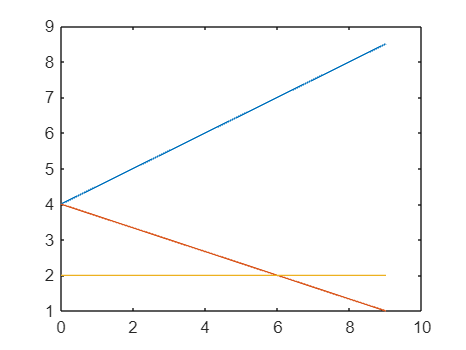

len = 0:9;
reals = zeros(3, length(len));
for i=len
    reals(1, i+1) = x1(i);
    reals(2, i+1) = x2(i);
    reals(3, i+1) = x3(i);
end

figure();
plot(len, reals);

b) Med visning af mellemregninger bestem ensemble middelværdien for processen 𝑋[𝑛]. 

syms n

% Symbolic way to do it
(mean(x1(n)) + mean(x2(n)) + mean(x3(n)))/3

$$ans = \frac{n}{18}+\frac{10}{3}$$


%% Manual way of doing it with integrals in the given space
meanx1 = int(x1(n), n, len(1), len(end))/9

$$meanx1 = \frac{25}{4}$$

meanx2 = int(x2(n), n, len(1), len(end))/9

$$meanx2 = \frac{5}{2}$$

meanx3 = int(x3(n), n, len(1), len(end))/9

$$meanx3 = 2$$

(meanx1 + meanx2 + meanx3)/3

$$ans = \frac{43}{12}$$

c) Er processen X[n] WSS (stationær i den brede forstand) og ergodisk? Svaret skal begrundes. 

Bemærk: Ensemble variansen for processen kan beregnes til: −1/4 ⋅ 𝑛^2 + 4/3 .

## Opgave 4 - Statistik

Vi vil teste en ny sensor til måling af vindstyrke og placerer den i en vindtunnel med en given vindhastighed. Vi laver 10 målinger af vindhastigheden, som er vist nedenfor:

% Enhed = m/s
maalinger = [18.65 23.03 20.72 19.93 20.71 19.79 19.87 21.48 21.40 21.41];


Vi kan gå ud fra, at hver af de 10 målinger kommer fra samme fordeling, er uafhængige og at de kommer fra en normalfordeling. 

a) Beregn sample middelværdi og varians af vindhastighed målingerne

middelvaerdi = sum(maalinger)/length(maalinger) % eller brug mean(maalinger)

middelvaerdi = 20.6990

% mean(maalinger)

varians = sum((maalinger-middelvaerdi).^2)/(length(maalinger)-1)

varians = 1.4827

% var(maalinger)

Vi ønsker at teste nulhypotesen 𝐻0 ∶ 𝜇 = 20 𝑚/𝑠 (dvs. at middelværdien af målingerne er 20 m/s). 

b) Hvilken test og test statistik benyttes? (begrund svaret) 

For at bruge nulhypotesen, som givet ovenfor, bruger vi hypotese test til at undersøge dataen. Vi kan yderligt aflæse at nulhypotesen bruger populations middelværdien (population mean) som sammenligningsværdi, så middelværdien er dermed vores test statistik.

c) Beregn p-værdi. Kan nulhypotesen afvises med et 5% signifikansniveau?


tval = (middelvaerdi-20)/(sqrt(varians)/sqrt(length(maalinger)))

tval = 1.8153


pval = 2*(1-tcdf(tval, length(maalinger)-1))

pval = 0.1029

Med et signifikansniveau på 5% kan vi ikke afkræfte nulhypotesen, da 10% er større end 5%.

For at teste sensoren, har vi for hver af de 10 målinger også målt en output-spænding fra sensoren og disse er givet nedenfor:

maalinger2 = [40.17 49.20 44.40 43.03 44.26 42.29 42.45 46.05 45.76 45.78];

Der laves nu en lineær regressionsmodel 𝑌 = 𝛼𝑋 + 𝛽, hvor 𝑋 er vindhastighed og 𝑌 er outputspænding. Her er 𝛼 hældningskoefficient, som vi kan estimere til 𝛼̂ = 2. Tilsvarende er 𝛽 intercept (offset), som vi kan estimere til 𝛽̂ = 3. 

d) Lav et scatter-plot af sammenhæng mellem 𝑋 (vindhastighed) og 𝑌 (output-spænding) udfra de givne målinger. 

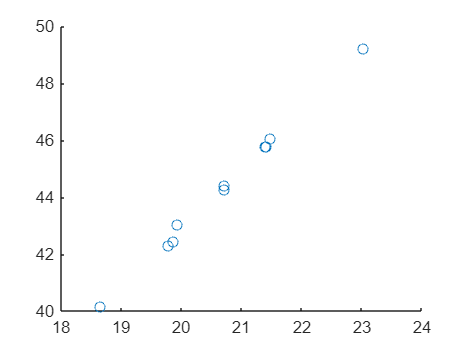

scatter(maalinger, maalinger2)

e) Lav et residual plot (et plot af residual værdierne for regressionsmodellen). 

residuals = maalinger2- (2*maalinger + 3)

residuals =    -0.1300    0.1400   -0.0400    0.1700   -0.1600   -0.2900   -0.2900    0.0900   -0.0400   -0.0400


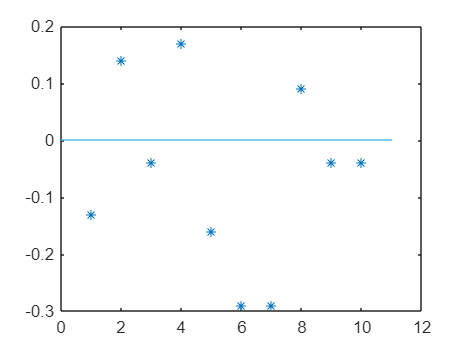

figure();
plot(1:length(maalinger2), residuals, '*', 0:length(maalinger2)+1, zeros(length(maalinger2)+2));
hold off;

f) Beregn sample korrelationskoefficienten mellem 𝑋 og 𝑌. Indikerer denne en stærk eller svag lineær sammenhæng imellem 𝑋 og 𝑌 ?


correlation = sum((maalinger-middelvaerdi).*(maalinger2-mean(maalinger2)))/(sqrt(sum((maalinger-middelvaerdi).^2)).*sqrt(sum((maalinger2-mean(maalinger2)).^2)))

correlation = 0.9986

correlation^2

ans = 0.9971